# Advection Diffusion Reaction Equation in 1D with homogeneous Dirichlet boundary conditions.

The following differential problem is given:

$\left\lbrace\begin{array}{cc}
 -u'' + 5u' + 12u = f  \quad  x \in (0,1) 
\\
u(0) = u(1) = 0
\end{array}
$,

with $f$ such that $u\left(x\right)=\sin \left(2\pi x\right)$ is the classical solution of the problem.

The following code implements Galerkin discretization method for the solution of the problem with an equally-spaced partition (the size of each element is equal to h).

The objective is to estimate the functional relation between the size of each element and the error of the numerical solution (calculated with an approximation of the $L^{2}(0,1)$ standard norm).

- The points of the partition will take a range from $2^2$ to $2^{11}$.

a = 0;
b = 1;
j = 2:11;
N = 2.^j;

- I define the coefficients of the equation.

mu = 1;
beta = 5;
sigma = 12;

- I define the classical solution of the problem and the function $f$ .

u = @(x) sin(2*pi*x);
f = @(x) (2.*pi).^2.*sin(2.*pi.*x) + 10.*pi.*cos(2.*pi.*x) + 12.*sin(2.*pi.*x);

- I define the error vector: for each partition (the numer of the partitions is given by the dimension of vector N) I calculate the discretization error due to the numerical solution $u_h$ given by the linear system.

error = zeros(length(N), 1);
h = zeros(length(N), 1);

- I solve the discretized problem for each $h$.

for i = 1:length(N)
    
    known_term = zeros(N(i) - 2);

    exact_solution = zeros(N(i) - 2,1);

    nodes = linspace(a,b, N(i));

    h(i) = nodes(2) - nodes(1);

    dd = 2*ones(N(i) - 2, 1);
    d1 = -1*ones(N(i) - 3, 1);

    D = (mu/h(i))*(diag(dd) + diag(d1, -1) + diag(d1,1));

    c1 = -1*ones(N(i) - 3, 1);
    c2 =  1*ones(N(i) - 3, 1);

    C = (beta/2)*(diag(c1, -1) + diag(c2,1));

    rr = (2/3)*ones(N(i) - 2, 1);
    r1 = (1/6)*ones(N(i) - 3, 1);

    R = (sigma*h(i))*(diag(rr) + diag(r1, -1) + diag(r1,1));
    
    A = D + C + R;

    for k= 2:(N(i) - 1)
        known_term(k - 1) = f(nodes(k));
        exact_solution(k - 1) = u(nodes(k));
    end

    known_term = h(i)*known_term;

    u_delta = A\known_term;

    for k= 1:length(exact_solution)
        error(i) = error(i) + (h(i)*(abs(exact_solution(k,1) - u_delta(k,1)))^2);
    end

    error(i) = sqrt(error(i));

end

coeff = polyfit(h, error, 2)

coeff =     5.0369   -0.1936    0.0015


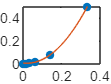


y = @(x) coeff(1)*x.^2 + coeff(2)*x + coeff(3);

pun = linspace(h(length(h)), h(1));
y_pun = y(pun);

plot(h, error, '.', 'markersize', 14)
hold on
plot(pun, y_pun)

The functional relation between the discretization error and the uniform size of each element by a quadratic fit of the data is:

$err(h) = c_{1} \cdot h^{2} + c_{2} \cdot h + c_{3}$, 

with $c_1$ = coeff(1) = 5.037, $c_{2}$ = coeff(2) = -0.1936, $c_3$ = coeff(3) = 0.001543.

Remark:  for very low value of the element size (for instance, from $h(6)$ = 0.00787) the function $y = c_{1} \cdot x^{2}$ gives a better approximation of the experimental data than the function above mentioned.